7.10 （ 事件）实时脚本

由张志涌编写、修改于 2023.1。

落体

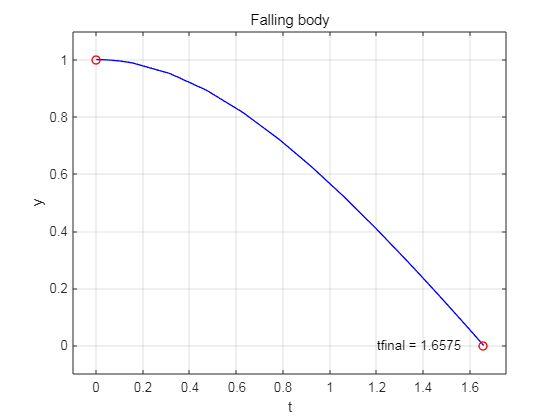

opts = odeset('events',@g);
y0 = [1; 0];
[t,y,tfinal] = ode45(@f,[0 Inf],y0,opts);
plot(t,y(:,1),'-b',[0 tfinal],[1 0],'or','LineWidth',1)
axis([-.1 tfinal+.1 -.1 1.1])
grid on
xlabel('t'),ylabel('y')
title('Falling body')
text(1.2, 0, ['tfinal = ' num2str(tfinal)])

二体问题

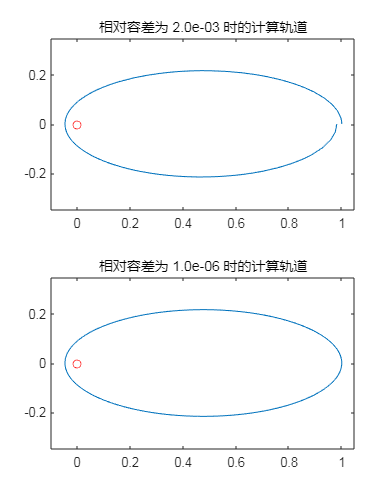

F=figure;
FP=F.Position;
F.Position=[FP(1:2),0.7*FP(3),1.2*FP(4)];
subplot(2,1,1)
rt3=2.0e-3;
[t3,y3]=orbit(rt3);
subplot(2,1,2)
rt6=1.0e-6;
[t6,y6]=orbit(rt6);

fprintf('%s %15s %29s\n','reltol','tfinal','yfinal')

reltol          tfinal                        yfinal


fprintf('%.1e  %.16f  [%.16f  %.16f]\n',rt3,t3,y3) 

2.0e-03  2.3508719776210589  [0.9810765990122112  -0.0001251913855516]


fprintf('%.1e  %.16f  [%.16f  %.16f]\n',rt6,t6,y6) 

1.0e-06  2.3802584617180482  [0.9999859390552269  0.0000000003223995]


function ydot = f(t,y)
    ydot = [y(2); -1+y(2)^2];
end
function [gstop,isterminal,direction] = g(t,y)
    gstop = y(1);
    isterminal = 1;
    direction = [];
end

